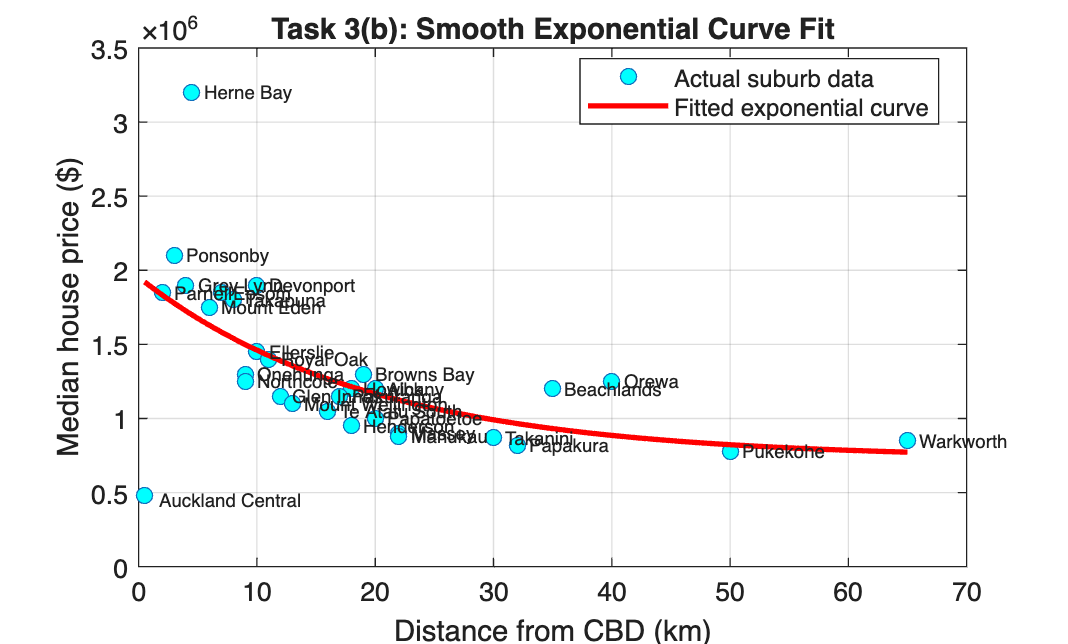

%% Task 3(b) - Fit a smooth curve using fminsearch
clear; clc; close all;

%% Define data directly
data = [
    0.5 480000; 2.0 1850000; 3.0 2100000;
    4.0 1900000; 4.5 3200000; 6.0 1750000;
    7.0 1850000; 9.0 1300000; 10.0 1450000;
    11.0 1400000; 12.0 1150000; 13.0 1100000;
    18.0 1200000; 17.0 1150000; 18.0 950000;
    16.0 1050000; 22.0 900000; 20.0 1200000;
    19.0 1300000; 9.0 1250000; 20.0 1000000;
    22.0 880000; 32.0 820000; 30.0 870000;
    50.0 780000; 35.0 1200000; 40.0 1250000;
    65.0 850000; 10.0 1900000; 8.0 1800000
];

suburbs = {'Auckland Central'; 'Parnell'; 'Ponsonby'; 'Grey Lynn'; 'Herne Bay';
    'Mount Eden'; 'Epsom'; 'Onehunga'; 'Ellerslie'; 'Royal Oak'; 'Glen Innes';
    'Mount Wellington'; 'Howick'; 'Pakuranga'; 'Henderson'; 'Te Atatu South';
    'Massey'; 'Albany'; 'Browns Bay'; 'Northcote'; 'Papatoetoe'; 'Manukau';
    'Papakura'; 'Takanini'; 'Pukekohe'; 'Beachlands'; 'Orewa'; 'Warkworth';
    'Devonport'; 'Takapuna'};

d = data(:,1);
y = data(:,2);

%% Define exponential decay model
% Price = theta1 * exp(theta2 * d) + theta3
modelFun = @(theta, d) theta(1) * exp(theta(2) * d) + theta(3);

%% Define error function
errorFun = @(theta) sum((y - modelFun(theta, d)).^2);

%% Initial guesses
theta0 = [2000000, -0.08, 800000];

%% Fit model
thetaFit = fminsearch(errorFun, theta0);

%% Smooth fitted curve
dSmooth = linspace(min(d), max(d), 200);
yFit = modelFun(thetaFit, dSmooth);

%% Plot data and fitted curve
figure;
plot(d, y, 'o', 'MarkerFaceColor', 'cyan');
hold on;
plot(dSmooth, yFit, 'r-', 'LineWidth', 2);

xlabel('Distance from CBD (km)');
ylabel('Median house price ($)');
title('Task 3(b): Smooth Exponential Curve Fit');
legend('Actual suburb data', 'Fitted exponential curve', 'Location', 'best');
grid on;


n = length(y);
for i = 1:n
    if strcmp(suburbs{i}, 'Auckland Central')
        text(d(i)+1.2, y(i)-30000, suburbs{i}, 'FontSize', 7);
    else
        text(d(i)+1, y(i), suburbs{i}, 'FontSize', 7);
    end
end



%% Display fitted parameters
disp('Fitted parameters theta = [theta1, theta2, theta3]:');

Fitted parameters theta = [theta1, theta2, theta3]:


disp(thetaFit);

   1.0e+06 *

    1.2234   -0.0000    0.7294




%% Calculate model error
yPred = modelFun(thetaFit, d);
SSE = sum((y - yPred).^2);

disp('Sum of Squared Errors:');

Sum of Squared Errors:


disp(SSE);

   5.5594e+12

